## Homework 2.1

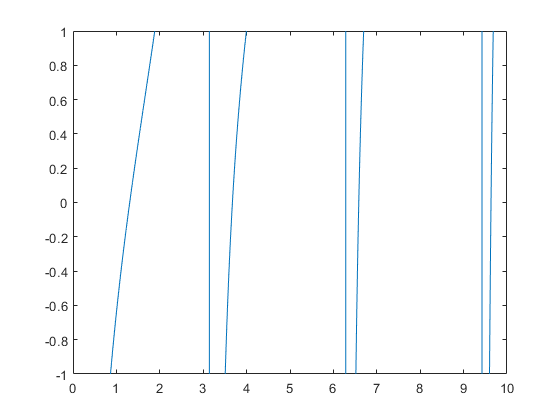

clear all;
close all;
clc;

f = @(x) (x.^2 - 1)./(2*x) - cot(x);

x = linspace(0, 10, 100000);

figure();
plot(x, f(x));
ylim([-1, 1]);

The three intervals are: [1, 3], [3.5, 4], [6.5, 6.7].

### Interval [1, 3]

a = 1;
b = 3;

tol = 10e-6;

[x, x_iter] = bisection(f, a, b, tol);

fprintf('x: %g', x);

x: 1.30654

display(x_iter);

x_iter =     2.0000    1.5000    1.2500    1.3750    1.3125    1.2813    1.2969    1.3047    1.3086    1.3066    1.3057    1.3062    1.3064    1.3065    1.3066    1.3065    1.3065    1.3065


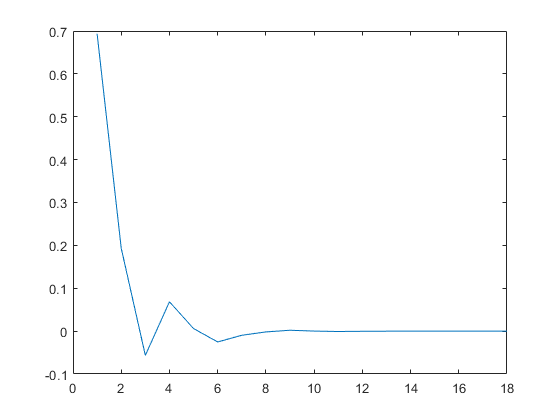


error = x_iter-x;
plot(error);

### Interval [3.5, 4]

a = 3.5;
b = 4;

tol = 10e-6;

[x, x_iter] = bisection(f, a, b, tol);

fprintf('x: %g', x);

x: 3.67319

display(x_iter);

x_iter =     3.7500    3.6250    3.6875    3.6563    3.6719    3.6797    3.6758    3.6738    3.6729    3.6733    3.6731    3.6732    3.6732    3.6732    3.6732    3.6732


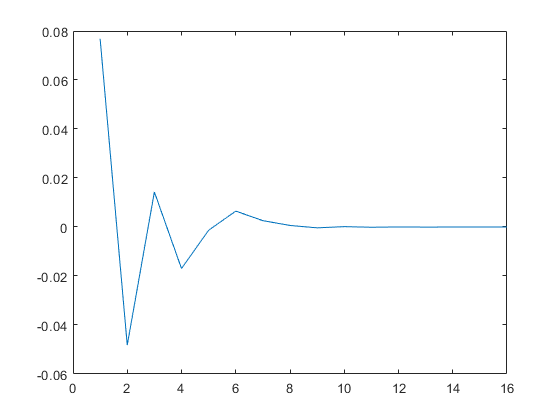


error = x_iter-x;
plot(error);

### Interval [6.5, 6.7]

a = 6.5;
b = 6.7;

tol = 10e-6;

[x, x_iter] = bisection(f, a, b, tol);

fprintf('x: %g', x);

x: 6.58463

display(x_iter);

x_iter =     6.6000    6.5500    6.5750    6.5875    6.5812    6.5844    6.5859    6.5852    6.5848    6.5846    6.5847    6.5846    6.5846    6.5846    6.5846


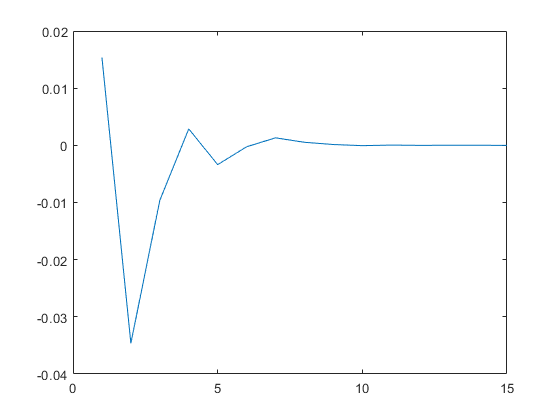


error = x_iter-x;
plot(error);

The biggest root among the ones contained in these 3 intervals is *x = 6.58463.*

Bisection function:

function [x, x_iter] = bisection(f, a, b, tol)
    Nmax = ceil(log((b-a)/tol)/log(2));
    
    for i = 1:Nmax
        x_iter(i) = (a+b)/2;
        
        if f(x_iter(i)) == 0
            break;
        end
        
        if f(x_iter(i)) * f(a) < 0
            b = x_iter(i);
        else
            a = x_iter(i);
        end
    end
    
    x = x_iter(end);
end